clc;
clear;


%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', contact, '/', exp, '/', rnn, network];


sensor = readmatrix(['../../../sensor_data_0.csv']);


pred = readmatrix(['../../../force_np.csv']);

pred_zero = readmatrix(['../../../zero_v_force_np.csv']);

pred_mul = readmatrix(['../../../simple_mtply.csv']);

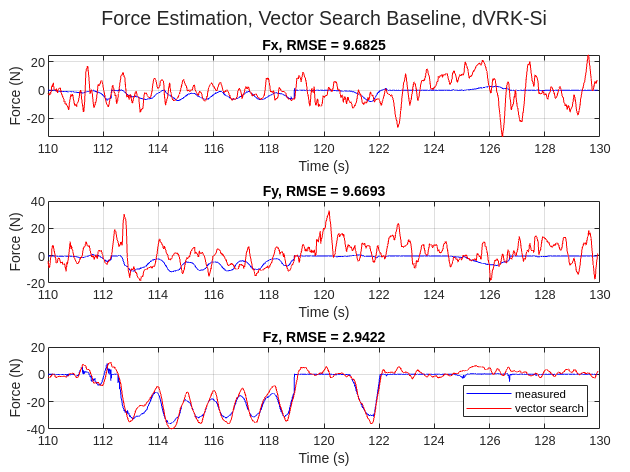



windowSize = 30; 
b = (1/windowSize)*ones(1,windowSize);
a = 1;


pred = filter(b,a,pred);


loss_x = mean(sqrt(mean( (pred(:,2) - sensor(1:length(pred),3)).^2 )));
loss_y = mean(sqrt(mean( (pred(:,3) - sensor(1:length(pred),4)).^2 )));
loss_z = mean(sqrt(mean( (pred(:,4) - sensor(1:length(pred),5)).^2 )));

loss_x_zero = mean(sqrt(mean( (pred_zero(:,2) - sensor(1:length(pred_zero),3)).^2 )));
loss_y_zero = mean(sqrt(mean( (pred_zero(:,3) - sensor(1:length(pred_zero),4)).^2 )));
loss_z_zero = mean(sqrt(mean( (pred_zero(:,4) - sensor(1:length(pred_zero),5)).^2 )));


loss_x_mul = mean(sqrt(mean( (pred_mul(:,2) - sensor(1:length(pred_mul),3)).^2 )));
loss_y_mul = mean(sqrt(mean( (pred_mul(:,3) - sensor(1:length(pred_mul),4)).^2 )));
loss_z_mul = mean(sqrt(mean( (pred_mul(:,4) - sensor(1:length(pred_mul),5)).^2 )));




figure()
tcl = tiledlayout(3,1, 'TileSpacing','Compact','Padding','Compact');

title(tcl, sprintf('Force Estimation, Vector Search Baseline, dVRK-Si'))


nexttile
plot(0.005*pred(22000:26000), sensor(22000:26000,3), 'b')
hold on
title(sprintf('Fx, RMSE = %.4f', loss_x))
plot(0.005*pred(22000:26000), pred(22000:26000,2), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
xlim([110 130])
grid on
hold off

nexttile
plot(0.005*pred(22000:26000), sensor(22000:26000,4), 'b')
hold on
title(sprintf('Fy, RMSE = %.4f', loss_y))
plot(0.005*pred(22000:26000), pred(22000:26000,3), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
xlim([110 130])
grid on
hold off

nexttile
plot(0.005*pred(22000:26000), sensor(22000:26000,5), 'b')
hold on
title(sprintf('Fz, RMSE = %.4f', loss_z))
plot(0.005*pred(22000:26000), pred(22000:26000,4), 'r')
xlabel('Time (s)')
ylabel('Force (N)')
xlim([110 130])
grid on
hold off

legend('measured', 'vector search', 'Location','southeast')

hold off